# **Chapter 19 Mini Quiz (Q2)**

Function

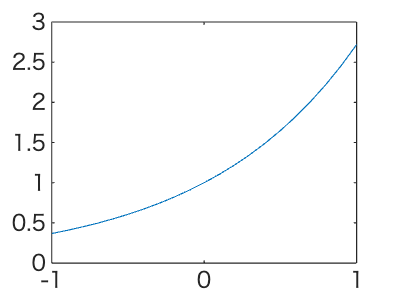

f=@(x) exp(x);
xx = a : 0.1 : b;
yy = f(xx);

plot(xx, yy, '-')

To integrate function from -1 to 1 *(doing analytical integration)*

format short
a = -1;
b = 1;
Itrue = exp(b) - exp(a) % for relative value

Itrue = 2.3504

Plot original function along with trapezoidal rule ns = 1 (single application)

ns = 1

ns = 1

% NEW
I_trap_ns1 = trap(f, a, b, ns)

I_trap_ns1 = 3.0862

err_ns1 = ((Itrue - I_trap_ns1) / Itrue) * 100

err_ns1 = -31.3035

Plot original function along with trapezoidal rule ns = 4

ns = 4

ns = 4

% NEW
I_trap_ns4 = trap(f, a, b, ns)

I_trap_ns4 = 2.3992

err_ns4 = ((Itrue - I_trap_ns4) / Itrue) * 100

err_ns4 = -2.0747

Single application of Simpson’s 1/3 rule (ns = 1)

y = f(x);
% NEW
h = (b - a) / 2

h = 1

I_simpson13_ns1 = (h/3) * (y(1) + 4*y(2) + y(3)) % formula from the slides (page 18)

I_simpson13_ns1 = 3.0643

err_simpson13_ns1 = ((Itrue - I_simpson13_ns1) / Itrue) * 100

err_simpson13_ns1 = -30.3726

# **TODO: FINISH CODE BELOW**

Composite Simpson’s 1/3 rule for 4 segments (ns = 4)

ns = 4

ns = 4

h = (b - a) / (2*ns)

h = 0.2500

for i = 1:ns
    % compute area for each segment
    simpson13_ns4(i) = (h/3) * (y(i) + 4*y(i + 1) + y(i + 2))
end

simpson13_ns4 = 0.7661

インデックスが配列要素数を超えています。インデックスは 3 を超えてはなりません。


% calculate total area
I_simpson13_ns4 = sum(simpson13_ns4)
err_simpson13_ns4 = ((Itrue - I_simpson13_ns4) / Itrue) * 100

Single application of Simpson’s 3/8 rule (ns = 1)

y = f(x);

% NEW
h = (b - a) / 3
I_simpson38_ns1 = (3*h/8) * (y(1) + 3*y(2) + 3*y(3) + 3*y(4)) % formula from the slides (page 18)
err_simpson38_ns1 = ((Itrue - I_simpson38_ns1) / Itrue) * 100

Composite Simpson’s 3/8 rule for 4 segments (ns = 4)

ns = 4
for i = 1:ns
    % compute area for each segment
    % h = (b - a) / (2*ns)
    % simpson
end